# Diffraction Script

This MATLAB sctipt works to calculate the diffraction caused by a pupil . Fourier Optics are used to model such simulation and the field is measured using Fraunhoffer. 

% Begin Script
clear; close all; clc;

## Define General Parameters

N=2.^8;                             %Definition of problem
lx=5;                               %Spatial limits
x=linspace(-lx,lx,N+1); x=x(1:N);   %Create an axis of cartesian space
[X,Y]=meshgrid(x);                  %Meshrid cartesian space 

## Define the shape of the pupil (aperture)

pupil ="pentagon";

switch pupil
    case "square"
        M=0.*X*Y;
        A=find(abs(X)<=0.3 & abs(Y)<=0.3);
        M(A)=1;
        
    case "circular"
        R=1;
        M=zeros(N);
        A=(X.^2+Y.^2<=R^2);
        M(A)=1;
        %GGG=((x-0.3).^2+y.^2<=0.2^2);
        %M(GGG)=0; 
        
    case "triangle"
        M = 0.*X*Y;
        A = (X >= Y.*(1/sqrt(3))-1);
        B = (X <= -Y*(1/sqrt(3))+1);
        C = Y>=0;
        M(A&B&C) = 1;
        
    case "double_slit"
        R = 0.5;
        M = 0.*X*Y;
        A = ((X-3).^2 + Y.^2 <= R^2);
        B = ((X+3).^2 + Y.^2 <= R^2);
        M(A) = 1;
        M(B) = 1;
        
    case "pentagon"
        M = 0.*X*Y;
        A = (X >= Y.*cotd(36)-2.12);
        B = (X <= -Y.*cotd(36)+2.12);
        C = (X <= Y.*cotd(72)+0.5);
        D = (X >= -Y.*cotd(72)-0.5);
        E = Y >= 0;
        M(A&B&C&D&E) = 1;   
end

clear pupil A 


## Calculate the Fraunhofer Integral

T=fftshift(fft2(M));

## Plot the results

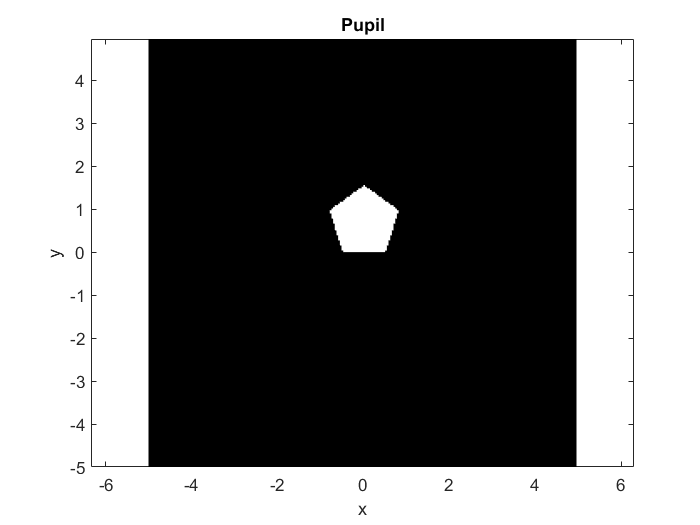

figure(1)
%imagesc(d)
pcolor(x,x,M)
colormap(gray)
shading flat;
axis equal;
title("Pupil")
xlabel("x")
ylabel("y")

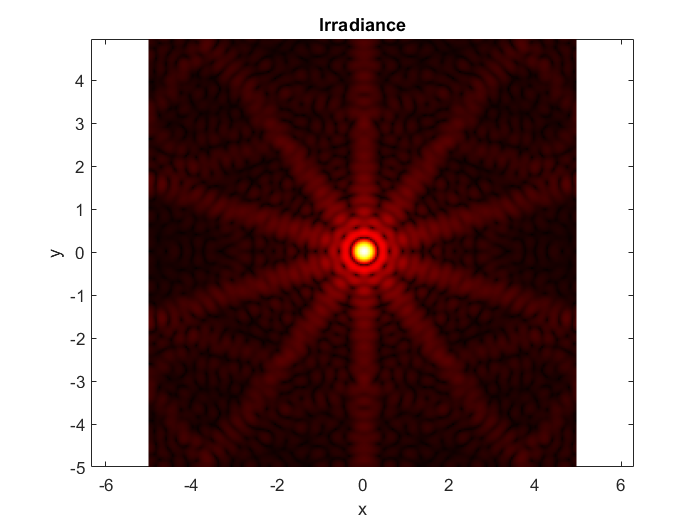


figure(2)
%pcolor(x,x,log(1+T.*conj(T)))
pcolor(x,x,sqrt(abs(T)))
shading flat;
axis equal;
%imshow(abs(TT).^2)
colormap(hot)
title("Irradiance")
xlabel("x")
ylabel("y")

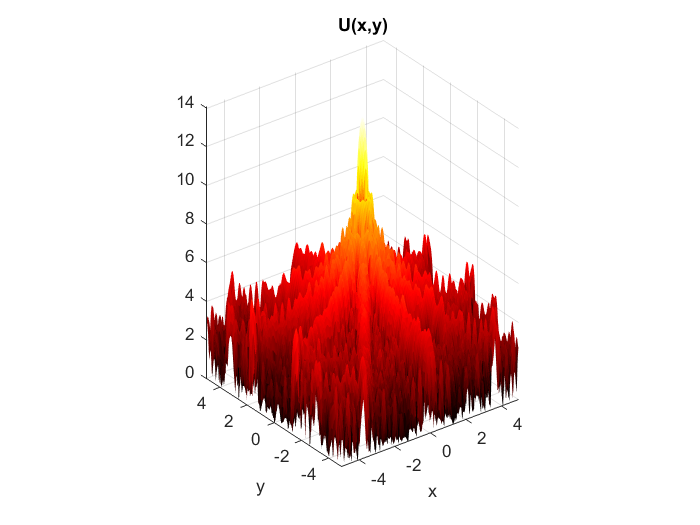



figure
surf(x,x,log(1+T.*conj(T)))
shading flat;
axis equal;
%imshow(abs(TT).^2)
colormap(hot)
title("U(x,y)")
xlabel("x")
ylabel("y")